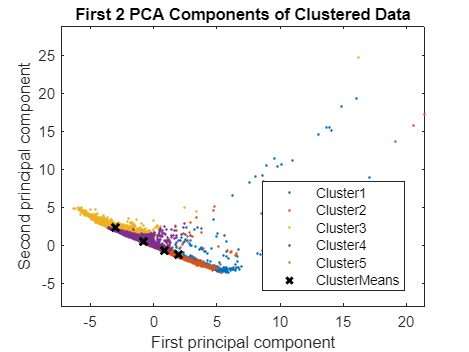

% Perform k-means clustering using specified number of clusters (K value)
K = 5;
[clusterIndices,centroids] = kmeans(stand_feature_matrix,K,"MaxIter",1000);
clear K

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score2] = pca(stand_feature_matrix);
clusterMeans = grpstats(score2,clusterIndices,"mean");
h = gscatter(score2(:,1),score2(:,2),clusterIndices,colormap("lines"));
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score2
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");